# 矩阵元素的引用

`在讲解矩阵元素的引用之前，我们先来回顾一下矩阵的表示方式：`


$$\left\lbrack \begin{array}{cccc}
a_{11}  & a_{12}  & \cdots  & a_{1n} \\
a_{21}  & a_{22}  & \cdots  & a_{2n} \\
\vdots  & \vdots  & \ddots  & \vdots \\
a_{m1}  & a_{\mathrm{m}2}  & \cdots  & a_{\mathrm{m}\mathrm{n}} 
\end{array}\right\rbrack$$


`上方给出了一个`$m$`行`$n$`列的矩阵，对于第`$i$`行,第`$j$`列的元素，我们用`$a_{\textrm{ij}}$`表示。`

**双下标索引**

`我们可以使用矩阵元素所处的行`(row)`和列`(column)`来进行引用矩阵的某一个元素，方式为：`a(row_ind, column_ind). 

a = randi([2,10],4,5)  % 生成一个随机矩阵

a =      7    10     9     8     7
     8     2     2     3     6
     5     9     4     8     9
     5    10     5     2     8


a(1,2)  % 第一行第二列的元素

ans = 10

a(2,end)  % 第二行最后一列的元素

ans = 6

a(2,[1 3])  % 第二行、第一三列的元素

ans =      8     2


a(3,1:5)  % 第三行、一至五列的元素

ans =      5     9     4     8     9


a([1 3], [1 3 5])    % 第一三行、第一三五列的元素

ans =      7     9     7
     5     4     9


a(1:2:end, 1:2:end)   % 奇数行且奇数列对应的元素

ans =      7     9     7
     5     4     9


`前面我们学过，可以使用`length`函数来计算向量中包含的元素个数。`

`那么，怎么计算一个矩阵的大小呢？我们可以使用`**size**`函数。有两种常见的用法：`

（1）size(A) 返回一个行向量，其元素是 A 的相应维度的长度。

A = ones(4,6) % 全为1的矩阵

A =      1     1     1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1


s = size(A)   % 返回[4,6]，表示有4行和6列

s =      4     6


（2）size(A,dim)`返回在维度`dim`上的长度。`dim=1表示行；dim=2表示列

r_num = size(A,1)  % 行数

r_num = 4

c_num = size(A,2)   % 列数

c_num = 6

注意：即使A是一个向量，size(A)返回的结果也是一个向量，而不是向量的长度。

A = 1:5;  % 行向量：[1 2 3 4 5]
size(A)

ans =      1     5


这里再补充一种用法，size函数可以有两个返回值

第一个返回的元素用来保存行数；第二个返回的元素用来保存列数

A = zeros(3,5)

A =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


[r, c] = size(A)

r = 3

c = 5

length`函数和`numel`函数也可以用在矩阵上。`

length`函数会返回行和列的较大值`

A = ones(3,4)

A =      1     1     1     1
     1     1     1     1
     1     1     1     1


length(A)

ans = 4

numel`函数会返回矩阵中元素的总数`

numel(A)

ans = 12

`有时候我们需要取出矩阵的某一行或者某一列。以取出矩阵`A`的第一行为例，我们可以使用代码`A(1, 1:end)`，即`row_ind`取`1`表示第一行，`column_ind`取`1:end`表示从`1`到最后一列的索引。`

A = randi([2,10],4,5) 

A =     10     3     6     9     4
    10     2    10     9     9
     5     8     7     7     2
     8     6     7     3     6


A(1,1:end)

ans =     10     3     6     9     4


`这时候我们可以直接将其简写为：`A(1, :)`，逗号后面是列索引的位置，加一个冒号就表示取出每一列的元素。`

A(1,:)

ans =     10     3     6     9     4


同理，要取第一列的所有元素，我们可以使用代码：A(:, 1)

A(:, 1)

ans =     10
    10
     5
     8


`总结：`

- `A(:, n)` `表示矩阵``A``的第``n``列的所有元素。`

- `A(m, :) ``表示矩阵``A``的第``m行的所有元素。`

`练习：`

`（1）生成一个5行7列的随机整数矩阵，元素位于区间[1,10]`

A = randi(10,5,7) 

A =      2     1     1     7     5     2     4
    10     7     9     6     5     4     6
     8     1     9    10     9     9     5
     6     1     8     7     1     9     7
     5     6     2     9     2     1     7


`（2）取出A的第2,5两列`

% A(:,[2,5])
% A(1:end,[2,5])

`（3）`取出A的最后一列

% A(:,end)
% A(:,size(A,2))

`（4）`取出A的偶数行

A(2:2:end, :)

ans =     10     7     9     6     5     4     6
     6     1     8     7     1     9     7


`（5）取出`A`的奇数行``、`3`的倍数列``的元素`

A(1:2:end, 3:3:end)

ans =      1     2
     9     9
     2     1


## `线性索引（单下标）`

`前面我们介绍的是对矩阵的双下标进行索引，即同时指定行索引和列索引，中间用逗号隔开。有同学会问，我们能不能使用单个下标对矩阵进行索引呢？在`MATLAB`中是可以的，这种``单下标的索引``方法称为线性索引``。`

`事实上，在`MATLAB`中，矩阵的数据在计算机的内存中被存储为单列。以下图为例，下面的矩阵虽然显示为` 3`×`3 `矩阵，但`MATLAB`在内存中将它存储为单列，由它的各列顺次连接而成。例如，第`2`行第`2`列的元素的线性索引为`5`，第`2`行第`3`列的元素的线性索引为`8`。`

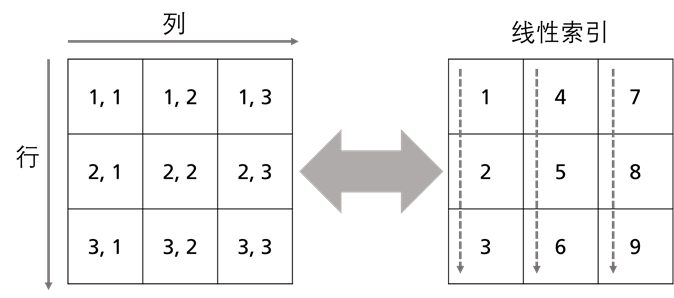

`我们可以利用线性索引来取出矩阵中的元素，尽管这种方式并不那么直观。`

举个例子：

A = randi(100,3,5) 

A =     30    99    38    34     6
    44    17    20    96    74
     2    11    49    93    27


A(5)

ans = 17

A(2:7)

ans =     44     2    99    17    11    38



A(1:2:end)

ans =     30     2    17    38    49    96     6    27


**A(:)命令可以将A中的所有元素按照线性索引的方式重构成一个列向量**`，这个命令后面会经常用到。`

A = randi(100, 2, 3)

A =     43    95    99
    55    42    31


A(:)

ans =     43
    55
    95
    42
    99
    31


A(1:end)

ans =     43    55    95    42    99    31


% 对向量也有同样的效果
a = [2 5 8 1];
a(:)

**sub2ind和ind2sub函数可用于在矩阵的原始索引(双下标)和线性索引之间进行转换，**用到频率不高。

sub2ind将矩阵的下标转换为线性索引

ind = sub2ind(sz,row,col) 针对大小为 sz 的矩阵返回由 row 和 col 指定的行列下标的对应线性索引 ind。此处，sz 是包含两个元素的向量，其中 sz(1) 指定行数，sz(2) 指定列数。

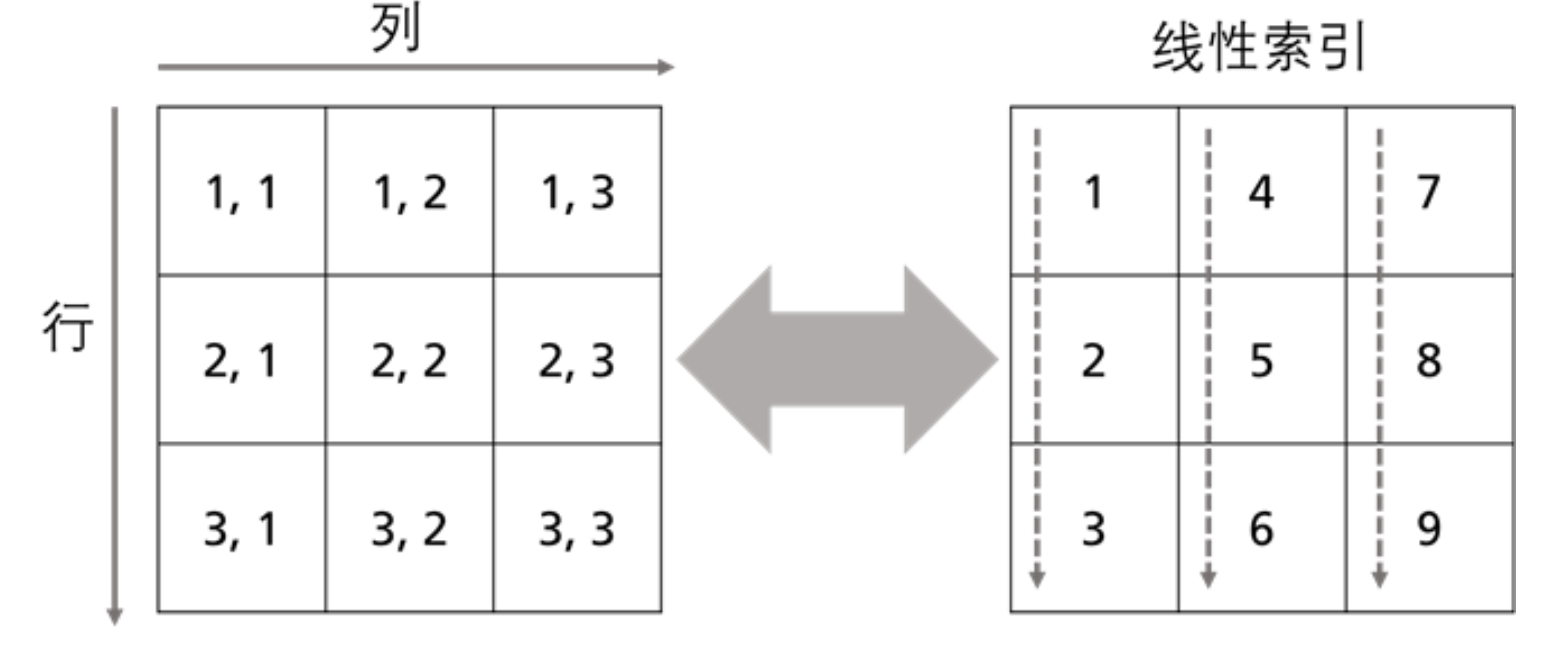

sub2ind([3,3],2,2)
sub2ind([3,3],1,3)

ans =      2
     5
     8
     1


ind2sub将线性索引转换为下标

[row,col] = ind2sub(sz,ind) 返回数组 row 和 col，其中包含与大小为 sz 的矩阵的线性索引 ind 对应的等效行和列下标。此处，sz 是包含两个元素的向量，其中 sz(1) 指定行数，sz(2) 指定列数。

[row,col] = ind2sub([3,3], 5) 

ans = 5

[row,col] = ind2sub([3,3], 7) 

ans = 7

row = 2

col = 2

row = 1

col = 3

配套的讲解视频可在b站免费观看：

《MATLAB教程新手入门篇（数学建模清风主讲，适合零基础同学观看）》

[https://www.bilibili.com/video/BV1dN4y1Q7Kt/](https://www.bilibili.com/video/BV1dN4y1Q7Kt/)